clear;
clc;


## parameters

c1 = 1/60;
c2 = 0.2;
c3 = 0.1;

syms p x1 x2 x3 x4 u real;
p = x3*u;%x3 and u are known, and if choose like this can insure the LPV model to be linear model

 

Exercise 1


A = [ 0 0 0 c1;
    0 -c2 0 0;
    0 c2 -c3 0;
    0 0 c3 -c1];
Ap = [-p, 0, 0, 0;
    p, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, 0, 0]; % 

B = [0 0 0 0]';
Bp = [0 0 0 0]';

%dot_x(t)=(A+Ap)p(t)x(t)+Bpu(t)+Bw(t)
%y = x3;
%endo, linear, polynomial, exact


## EXERCISE 2

x0 = [0.6, 0.3, 0.1, 0]';  
T = 100;  
tspan = [0 T];
% t = 1:0.01:T;
u = [0, 0.3, 0.8];
% ucontrol = [0, 0.3, 0.8];

figure;
hold on;
grid on;
for i = 1:length(u)
    ode = @(t, x) [
        -u(i)*x(1)*x(3) + c1*x(4);
        u(i)*x(1)*x(3) - c2*x(2);
        c2*x(2) - c3*x(3);
        c3*x(3) - c1*x(4)
    ];
    [t, x] = ode45(ode, tspan, x0);

    plot(t, x(:,3));
%     title(['Control Input u(t) = ', num2str(u(i))]);
    xlabel('Time');
    ylabel('States');
%     legend('x1', 'x2', 'x3', 'x4');
    fprintf('For u(t) = %f, sum(x(T)) = %f, sum(x(0)) = %f\n', u(i), sum(x(end,:)), sum(x0));
end

For u(t) = 0.000000, sum(x(T)) = 1.000000, sum(x(0)) = 1.000000
For u(t) = 0.300000, sum(x(T)) = 1.000000, sum(x(0)) = 1.000000
For u(t) = 0.800000, sum(x(T)) = 1.000000, sum(x(0)) = 1.000000


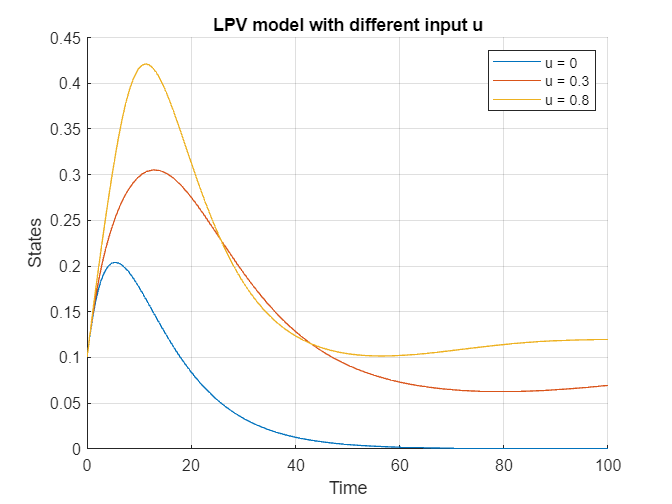



title('LPV model with different input u');
legend('u = 0','u = 0.3','u = 0.8');

% People never add, so the total amount keeps

% Sum = x1 + x2 +x3 +x4
% dot_sum = dot_x1 + dot_x2 + dot_x3 + dot_x4 == 0;


## New excer2

clear;
clc
c1 = 1/60;
c2 = 0.2;
c3 = 0.1;

A = [0, 0, 0, c1;
    0, -c2, 0, 0;
    0, c2, -c3, 0;
    0, 0, c3, -c1];

x0 = [0.6, 0.3, 0.1, 0]';  

T = 100;  
dt = 0.01; 
t = 0:dt:T;
ucontrol = [0, 0.3, 0.8];

figure;
hold on;
grid on;
disp('Initial value:');

Initial value:


disp(sum(x0));

    1.0000



% smimulate
for i = 1:length(ucontrol)
    u = ucontrol(i);
    x = zeros(4, length(t));
    x(:,1) = x0;
    
    for k = 2:length(t)
        p = x(3,k-1) * u; 
        Ap = [-p, 0, 0, 0;
              p, 0, 0, 0;
              0, 0, 0, 0;
              0, 0, 0, 0]; % 
        dx = (A + Ap) * x(:,k-1) * dt;
        x(:,k) = x(:,k-1) + dx;
    end
    plot(t, x(3,:));
    disp('Final value:');
    disp(sum(x(:,end)));
end

Final value:


    1.0000



Final value:


     1



Final value:


    1.0000



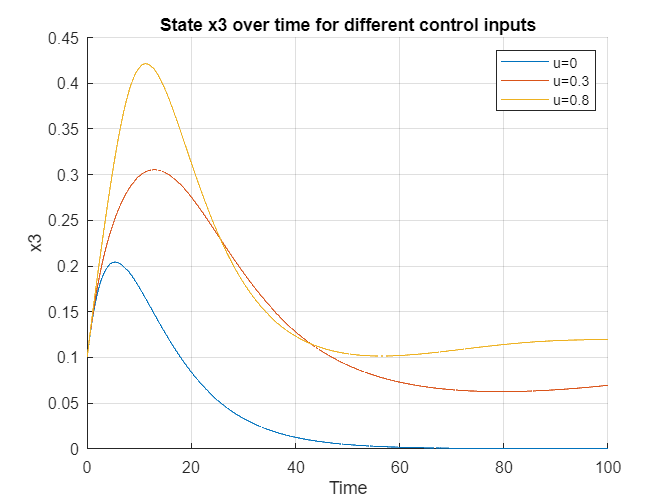


xlabel('Time');
ylabel('x3');
legend('u=0', 'u=0.3', 'u=0.8');
title('State x3 over time for different control inputs');

## Exercise3

AP =[-p,    0,     0,  1/60;
 p, -1/5,     0,     0;
    0,  1/5, -1/10,     0;
   0,    0,  1/10, -1/60]

O1 = [0 0 1 0]; % y = [0 0 1 0]x3
dot_O1 = 0;
O2 = dot_O1 + O1 * AP
dot_O2 = 0;
O3 = dot_O2 + O2 * AP
syms dotp;
dot_O3 = [0.2*dotp 0 0 0];
O4 = dot_O3 + O3 * AP
OBO = [O1' O2' O3' O4']'
rank(OBO)
% p =0, then lose rank


## Excercise4